# State Space Models

We begin by writing the state space model for a an *individual (Ai)* axis

syms I I_dot theta_ddot_m V_s R_m L_m V_emf theta_dot_m tau_m G theta_dot_g b J K_e K_i

u_i = V_s

$$u\_i = V_{s}$$


x_i = [
    I
    theta_dot_m
]

$$x\_i = \left(\begin{array}{c} \text{I}\\ {\dot{\theta }}_{m} \end{array}\right)$$

latex(x_i)

ans = '\left(\begin{array}{c} I\\ \dot{\theta }_{m} \end{array}\right)'


x_dot_i = [
    I_dot
    theta_ddot_m
]

$$x\_dot\_i = \left(\begin{array}{c} \dot{I}\\ {\ddot{\theta }}_{m} \end{array}\right)$$


A_i = [
    -R_m/L_m      -K_e;
    -K_i/(J*G^2)  b/J
]

$$A\_i = \left(\begin{array}{cc} -\frac{R_{m}}{L_{m}} & -K_{e}\\ -\frac{K_{i}}{G^{2}\,J} & \frac{b}{J} \end{array}\right)$$

B_i = [
    1/L_m;
    0
]

$$B\_i = \left(\begin{array}{c} \frac{1}{L_{m}}\\ 0 \end{array}\right)$$

## State Space Models for Individual Axis

syms I_pan  I_dot_pan  theta_ddot_m_pan  V_s_pan R_m_pan L_m_pan V_emf_pan theta_dot_m_pan tau_m_pan G_pan theta_dot_g_pan b_pan J_pan K_e_pan K_i_pan
syms I_tilt I_dot_tilt theta_ddot_m_tilt V_s_tilt R_m_tilt L_m_tilt V_emf_tilt theta_dot_m_tilt tau_m_tilt G_tilt theta_dot_g_tilt b_tilt J_tilt K_e_tilt K_i_tilt

s      = [ I      I_dot      theta_ddot_m      V_s      R_m L_m V_emf theta_dot_m      tau_m      G      theta_dot_g      b      J      K_e K_i ];
s_pan  = [ I_pan  I_dot_pan  theta_ddot_m_pan  V_s_pan  R_m L_m V_emf theta_dot_m_pan  tau_m_pan  G_pan  theta_dot_g_pan  b_pan  J_pan  K_e K_i ];
s_tilt = [ I_tilt I_dot_tilt theta_ddot_m_tilt V_s_tilt R_m L_m V_emf theta_dot_m_tilt tau_m_tilt G_tilt theta_dot_g_tilt b_tilt J_tilt K_e K_i ];


x_pan  = subs(x_i, s, s_pan)

$$x\_pan = \left(\begin{array}{c} I_{\mathrm{pan}}\\ {\dot{\theta }}_{m,\mathrm{pan}} \end{array}\right)$$

x_tilt = subs(x_i, s, s_tilt)

$$x\_tilt = \left(\begin{array}{c} I_{\mathrm{tilt}}\\ {\dot{\theta }}_{m,\mathrm{tilt}} \end{array}\right)$$


x_dot_pan  = subs(x_dot_i, s, s_pan);
x_dot_tilt = subs(x_dot_i, s, s_tilt);

u_pan  = subs(u_i, s, s_pan);
u_tilt = subs(u_i, s, s_tilt);

A_pan  = subs(A_i, s, s_pan)

$$A\_pan = \left(\begin{array}{cc} -\frac{R_{m}}{L_{m}} & -K_{e}\\ -\frac{K_{i}}{{G_{\mathrm{pan}}}^{2}\,J_{\mathrm{pan}}} & \frac{b_{\mathrm{pan}}}{J_{\mathrm{pan}}} \end{array}\right)$$

A_tilt  = subs(A_i, s, s_tilt)

$$A\_tilt = \left(\begin{array}{cc} -\frac{R_{m}}{L_{m}} & -K_{e}\\ -\frac{K_{i}}{{G_{\mathrm{tilt}}}^{2}\,J_{\mathrm{tilt}}} & \frac{b_{\mathrm{tilt}}}{J_{\mathrm{tilt}}} \end{array}\right)$$

B_pan  = subs(B_i, s, s_pan)

$$B\_pan = \left(\begin{array}{c} \frac{1}{L_{m}}\\ 0 \end{array}\right)$$

B_tilt  = subs(B_i, s, s_tilt)

$$B\_tilt = \left(\begin{array}{c} \frac{1}{L_{m}}\\ 0 \end{array}\right)$$

We can now combine these into one large model

x = [ x_pan; x_tilt ]

$$x = \left(\begin{array}{c} I_{\mathrm{pan}}\\ {\dot{\theta }}_{m,\mathrm{pan}}\\ I_{\mathrm{tilt}}\\ {\dot{\theta }}_{m,\mathrm{tilt}} \end{array}\right)$$

x_dot = [ x_dot_pan; x_dot_tilt ]

$$x\_dot = \left(\begin{array}{c} {\dot{I}}_{\mathrm{pan}}\\ {\ddot{\theta }}_{m,\mathrm{pan}}\\ {\dot{I}}_{\mathrm{tilt}}\\ {\ddot{\theta }}_{m,\mathrm{tilt}} \end{array}\right)$$


A = [
    A_pan    zeros(2);
    zeros(2) A_tilt
]

$$A = \left(\begin{array}{cccc} -\frac{R_{m}}{L_{m}} & -K_{e} & 0 & 0\\ -\frac{K_{i}}{{G_{\mathrm{pan}}}^{2}\,J_{\mathrm{pan}}} & \frac{b_{\mathrm{pan}}}{J_{\mathrm{pan}}} & 0 & 0\\ 0 & 0 & -\frac{R_{m}}{L_{m}} & -K_{e}\\ 0 & 0 & -\frac{K_{i}}{{G_{\mathrm{tilt}}}^{2}\,J_{\mathrm{tilt}}} & \frac{b_{\mathrm{tilt}}}{J_{\mathrm{tilt}}} \end{array}\right)$$

B = [
    B_pan              zeros(size(B_pan));
    zeros(size(B_pan)) B_tilt
]

$$B = \left(\begin{array}{cc} \frac{1}{L_{m}} & 0\\ 0 & 0\\ 0 & \frac{1}{L_{m}}\\ 0 & 0 \end{array}\right)$$

% Defining outputs to be the velocities
C = [
    0 1 0 0;
    0 0 0 1
];
D = 0;

u = [ u_pan; u_tilt ]

$$u = \left(\begin{array}{c} V_{s,\mathrm{pan}}\\ V_{s,\mathrm{tilt}} \end{array}\right)$$

## Adding Real Parameters

G_tilt_real = 15/48; % measured by counting gear teeth on the system
G_pan_real = G_tilt_real;

% Use moment of inertia calculated in 'inertia.mlx'
J_tilt_real = vpa(J_tilt_real)

$$J\_tilt\_real = 0.021253995$$

J_pan_real = vpa(J_pan_real)

$$J\_pan\_real = 0.0433130440995\,{\sin\left(\theta_{\mathrm{tilt}}\right)}^{2}+0.059756512932$$

% Motor constants (K_e = K_i in SI units)
K_i_real = 0.509;
K_e_real = K_i_real;
R_m_real = 7.101;
L_m_real = 3.4E-3;

% Friction coefficients
b_pan_real  = 0 % TODO: system identification

b_pan_real = 0

b_tilt_real = 0 % TODO: system identification

b_tilt_real = 0



% substitute into the model
s      = [ b_pan      b_tilt      L_m      G_pan      b_pan J_pan      K_e_pan  R_m      L_m_tilt G_tilt      b_tilt J_tilt      K_e      K_i      ];
s_real = [ b_pan_real b_tilt_real L_m_real G_pan_real b_pan J_pan_real K_e_real R_m_real L_m_real G_tilt_real b_tilt J_tilt_real K_e_real K_i_real ];

A_real = vpa(subs(A, s, s_real), 3)

$$A\_real = \left(\begin{array}{cccc} -2090.0 & -0.509 & 0 & 0\\ -\frac{5.21}{0.0433\,{\sin\left(\theta_{\mathrm{tilt}}\right)}^{2}+0.0598} & 0 & 0 & 0\\ 0 & 0 & -2090.0 & -0.509\\ 0 & 0 & -245.0 & 0 \end{array}\right)$$

B_real = vpa(subs(B, s, s_real), 4)

$$B\_real = \left(\begin{array}{cc} 294.1 & 0\\ 0 & 0\\ 0 & 294.1\\ 0 & 0 \end{array}\right)$$

y = C*x + D*u

$$y = \left(\begin{array}{c} {\dot{\theta }}_{m,\mathrm{pan}}\\ {\dot{\theta }}_{m,\mathrm{tilt}} \end{array}\right)$$

# Controlability

Con = [B_real A_real*B_real];
rank(Con)

ans = 4

The system is controlable as the controlability has rank equal to the number of system state variables

# Regulator - State Feedback

t_s = 1;
alpha = 5;
sigma = -log(alpha/100)/t_s

sigma = 2.9957

A_e = [
        A_real zeros(4,2);
        C zeros(2,2);
   ]

$$A\_e = \left(\begin{array}{cccccc} -2088.529411792755126953125 & -0.5090000000054715201258659362793 & 0 & 0 & 0 & 0\\ -\frac{5.2121599999954923987388610839844}{0.0433130440995\,{\sin\left(\theta_{\mathrm{tilt}}\right)}^{2}+0.059756512932} & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & -2088.529411792755126953125 & -0.5090000000054715201258659362793 & 0 & 0\\ 0 & 0 & -245.23201402842148029111703470336 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0 \end{array}\right)$$

B_e = [
        B_real;
        zeros(2,2);
]

$$B\_e = \left(\begin{array}{cc} 294.117647059261798858642578125 & 0\\ 0 & 0\\ 0 & 294.117647059261798858642578125\\ 0 & 0\\ 0 & 0\\ 0 & 0 \end{array}\right)$$

C_e = [
        C zeros(2,2);
]

C_e =      0     1     0     0     0     0
     0     0     0     1     0     0


## Place Poles

poles = [-5 -5 -6 -6 -7 -7];

%A_e = double(vpa(subs(A_e, theta_tilt, t)))

F_e = @(t) place(double(subs(A_e, theta_tilt, t)), -double(B_e), poles)

F_e = function_handle with value:
    @(t)place(double(subs(A_e,theta_tilt,t)),-double(B_e),poles)



F = @(t) split_F(F_e(t));
FI = @(t) split_FI(F_e(t));

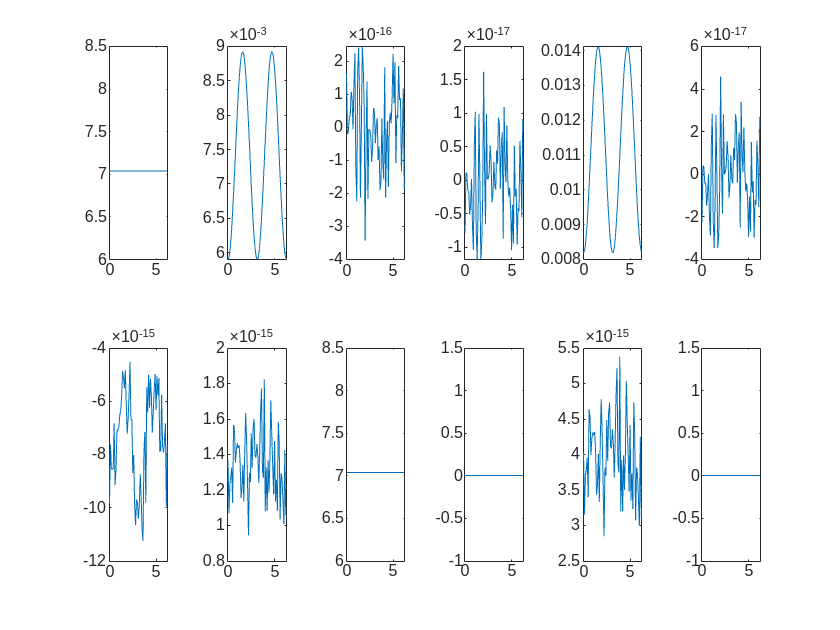


out = plot_matrix(F_e, 2, 6);


x = out(1, :);

Fe11 = out(2, :);
Fe21 = out(3, :);
Fe31 = out(4, :);
Fe41 = out(5, :);
Fe51 = out(6, :);
Fe61 = out(7, :);

Fe12 = out(8, :);
Fe22 = out(9, :);
Fe32 = out(10, :);
Fe42 = out(11, :);
Fe52 = out(12, :);
Fe62 = out(13, :);

# Fitting the Fields

Fitting sinusoidal looking fields

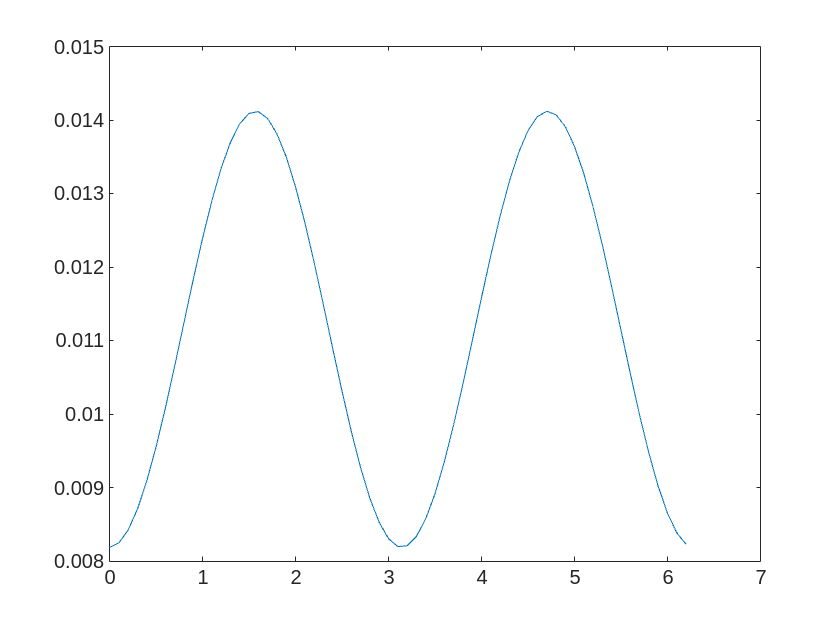

modelfun = 'y ~ b1*sin(x1*b2 + b3) + b4';
plot(x, Fe51)

Fe51_mdl = fitnlm(x, Fe51, modelfun, [1 1 1 1]);
b = Fe51_mdl.Coefficients.Estimate;
Fe51_reg = vpa(b(1) * sin(theta_tilt * b(2) + b(3)) + b(4), 4)

$$Fe51\_reg = 0.002967\,\sin\left(2.0\,\theta_{\mathrm{tilt}}-7.854\right)+0.01115$$

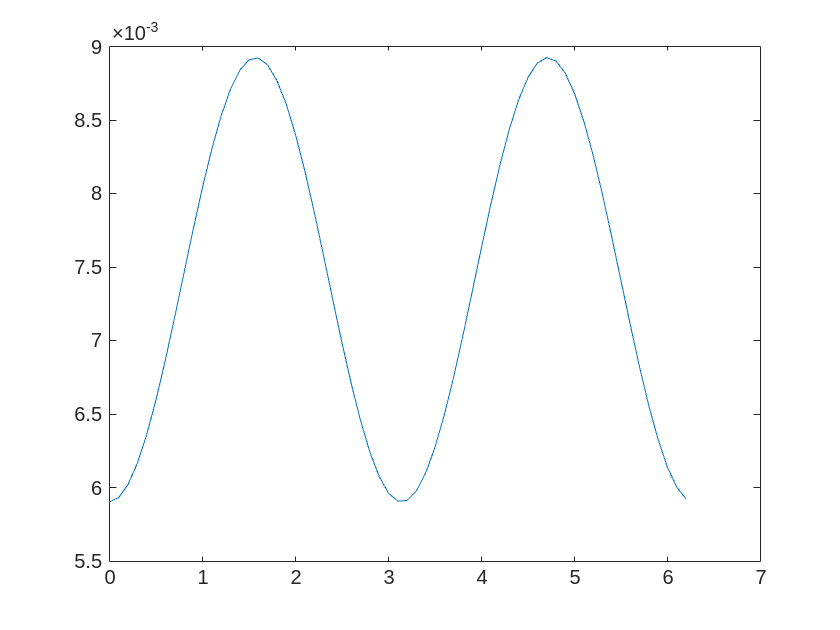

plot(x, Fe21)

Fe21_mdl = fitnlm(x, Fe21, modelfun, [1 1 1 1]);
b = Fe21_mdl.Coefficients.Estimate;
Fe21_reg = vpa(b(1) * sin(theta_tilt * b(2) + b(3)) + b(4), 4)

$$Fe21\_reg = 5.113e-5\,\sin\left(24.44\,\theta_{\mathrm{tilt}}-71.05\right)+0.00741$$